Vytvoření melspektrogramů + uložení obrázků

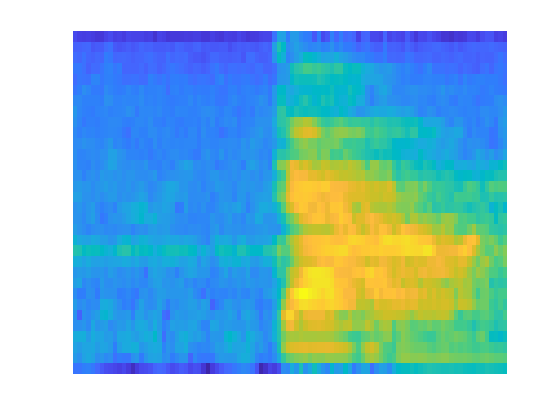

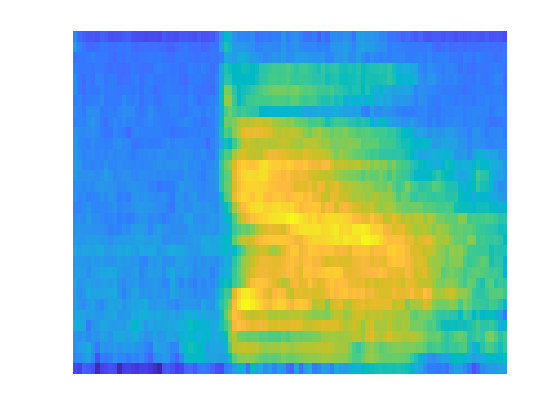

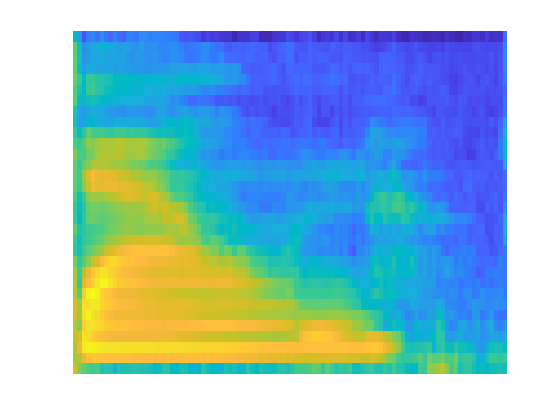

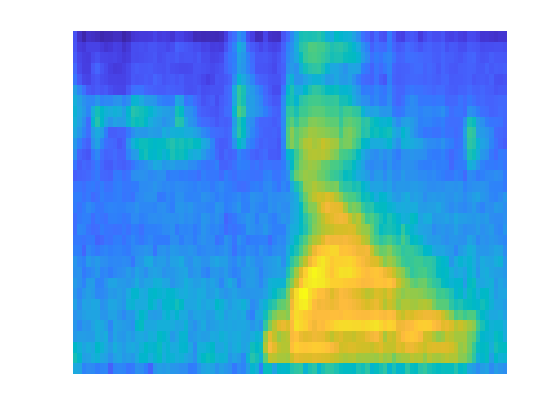

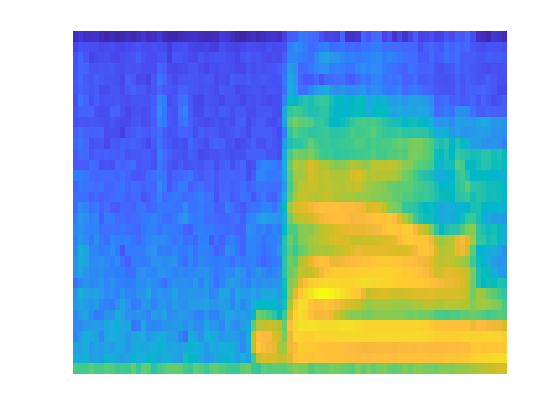

clear

folder='C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\hruskovicova-projekt\smallDataset\down-small';
subfolder = 'C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\hruskovicova-projekt\smallDataSetImg\down';
audio_files = dir(fullfile(folder,'*.wav'));

for i = 1:numel(audio_files)
    filename=audio_files(i).name;
    [data,Fs] = audioread(fullfile(folder,filename));
    AudioData{i}=data(:,1);
    f = figure;
    melSpectrogram(AudioData{i}, Fs);
    set(gca, 'Visible', 'off');
    colorbar('off');
    audio_files(i).name = audio_files(i).name(1:end-4);
    saveas(f, fullfile(subfolder, audio_files(i).name + ".png"));
end

Vytvoření obrázkové databáze

imageDatasetPath = fullfile('smallDataSetImg');
imds = imageDatastore(imageDatasetPath, 'IncludeSubfolders', true, 'LabelSource','foldernames');

Rozdělení dat (test, valid, train)

[imdsTrain,imdsValidation] = splitEachLabel(imds, 0.7, 'randomize');
[imdsValidation, imdsTest] = splitEachLabel(imdsValidation, 0.5, 'randomized');

CNN (nastavení a trénování)

I = imread('smallDataSetImg\down\0a7c2a8d_nohash_0.png')

I = 656×875×3 uint8 array
I(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  

imagesize = size(I)

imagesize =    656   875     3


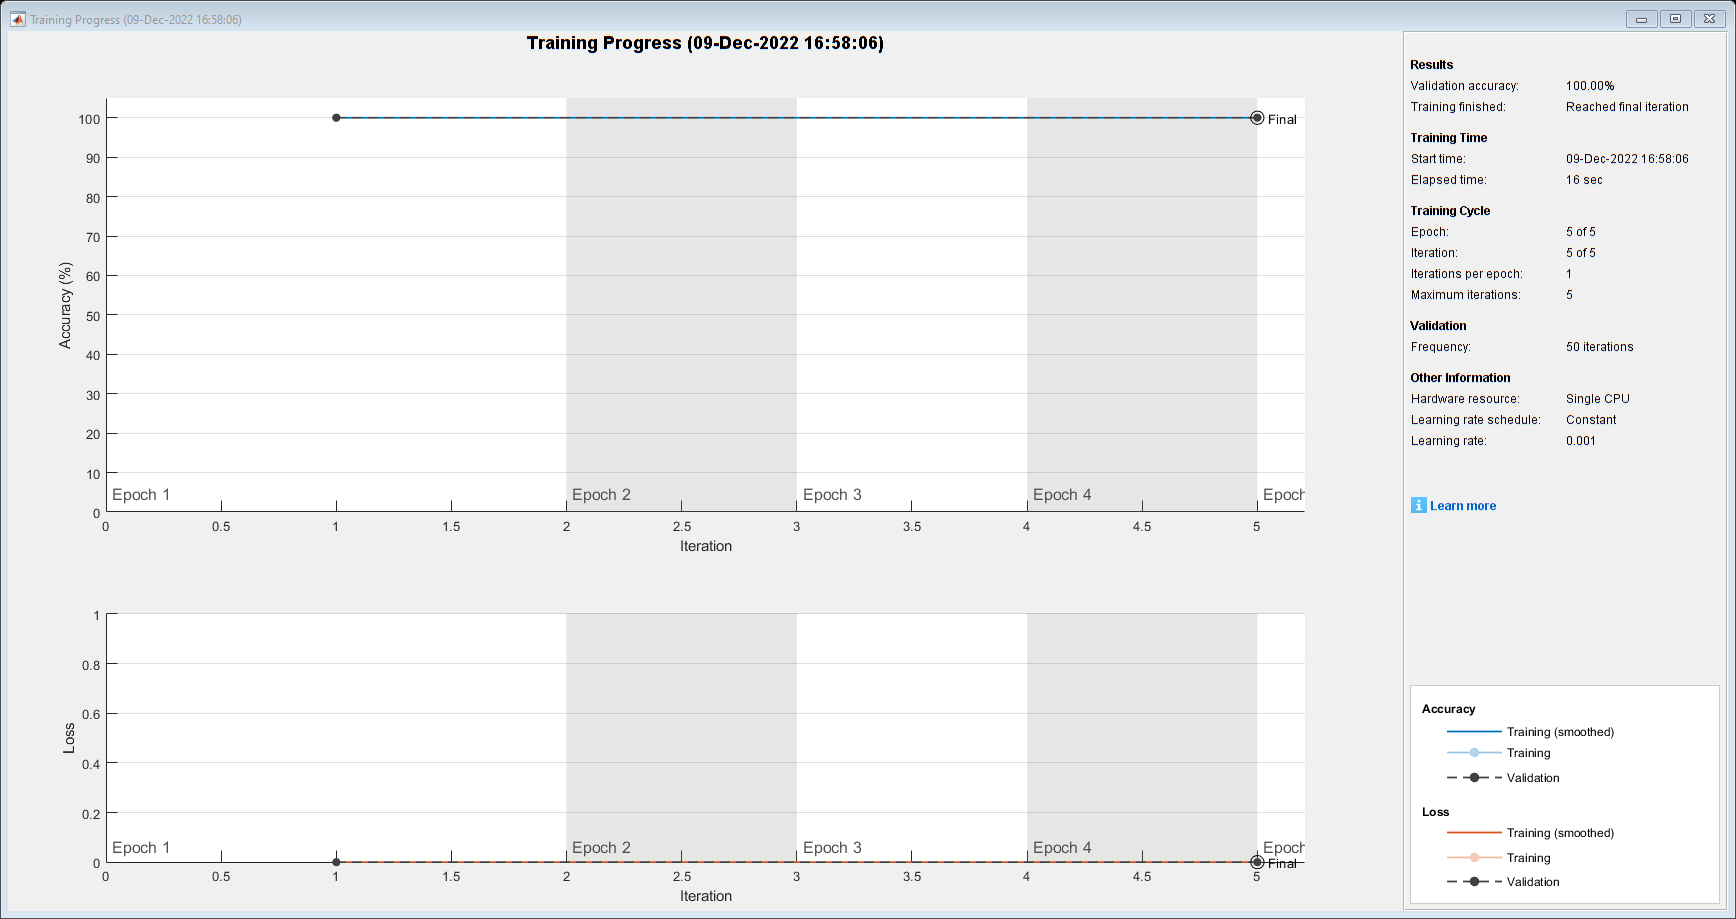


%numClasses = numel(Labels(imdsTrain));
numClasses = 1;

layers = [
    imageInputLayer(imagesize)

    convolution2dLayer(3,12,'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,2*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer([1 13])

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs',5, ...
    'Shuffle',"every-epoch",...
    "Plots",'training-progress',...
    "Verbose",false,...
    'ValidationData',imdsValidation);

net = trainNetwork(imdsTrain, layers, options);

vysledky = classify(net, imdsTest)

Error using DAGNetwork/calculatePredict>predictBatch (line 151)
Incorrect input size. The input images must have a size of [656 875 3].

Error in DAGNetwork/calculatePredict (line 17)
    Y = predictBatch( ...

Error in 